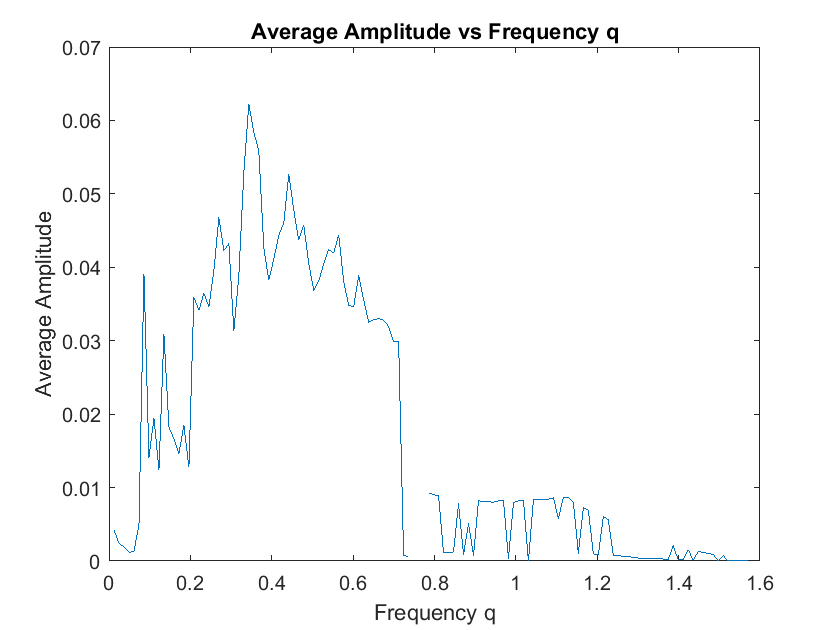

clc
clear

files = dir('*.mat');
for file = files'
    load(file.name);
    
    path = [file.name '_heatmap_plots/'];
    
    if ~exist(path, 'dir')
       mkdir(path)
    end
    
    filename = 'Average Amplitude vs Frequency q.png';
    plot(cilia.Results(1).qVec,cilia.Results(1).AverageAmplitude_vs_q)
    xlabel('Frequency q')
    ylabel('Average Amplitude')
    title('Average Amplitude vs Frequency q')
    saveas(gcf,[path filename])
    clf
    
    max_Iqtau=max(max(cilia.Results(1).Box(1).Iqtau));
    for tau =1:size(cilia.Results(1).Box(1).Iqtau,2)
        filename = ['ISF-q plot at tau=' num2str(tau/10) 's.png'];
        plot(0.5*cilia.Results(1).qVec,cilia.Results(1).Box(1).Iqtau(1:128,tau))
        ylim([0 max_Iqtau])
        xlabel('Frequency q')
        ylabel('ISF')
        title(['ISF-q plot at tau=' num2str(tau/10) 's'])
        saveas(gcf,[path filename])
        clf
    end
end

load('fx_0.05_fy_0.05_fxy_0_tauc_0_xc_0_yc_0_freq_0.2.mat');

disp(cilia.Results(1))

                  BoxSize: 512
               row_offset: 1
               col_offset: 1
           ind_good_boxes: 1
                      Box: [1×1 struct]
       MedianFrequencyVec: 10.0000
      AverageDamping_vs_q: [128×1 double]
    AverageAmplitude_vs_q: [128×1 double]
                     qVec: [1×128 double]
       MedianDamping_vs_q: [128×1 double]
     MedianAmplitude_vs_q: [128×1 double]



disp(cilia.Results(1).Box(1))

         std_fs: []
          Iqtau: [256×50 double]
    NonAvgIqtau: [512×512×50 single]
      Frequency: [128×1 double]
      Amplitude: [128×1 double]
        Damping: [128×1 double]
         Offset: [128×1 double]
            GOF: [128×1 double]
       lstd_sfd: []



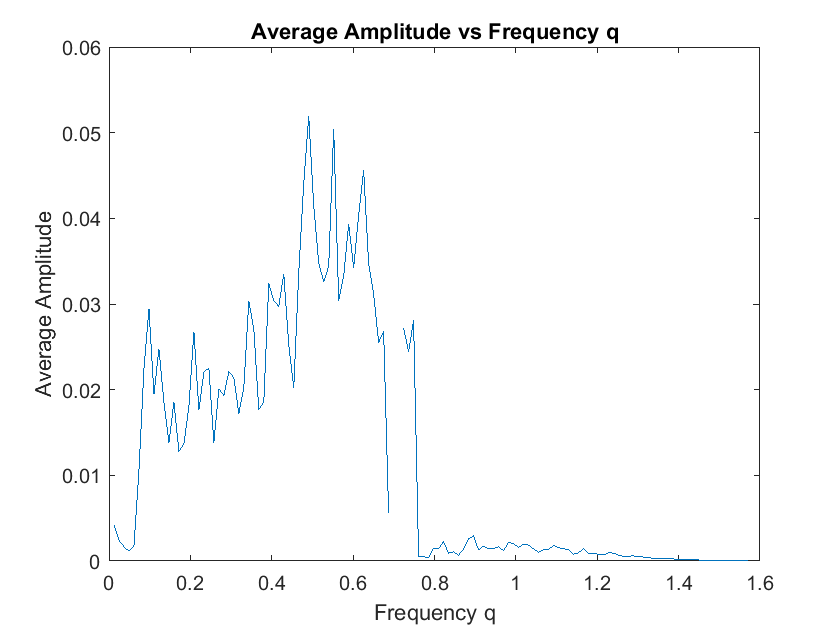

plot(cilia.Results(1).qVec,cilia.Results(1).AverageAmplitude_vs_q)
xlabel('Frequency q')
ylabel('Average Amplitude')
title('Average Amplitude vs Frequency q')

saveas(gcf,[path filename])
clf

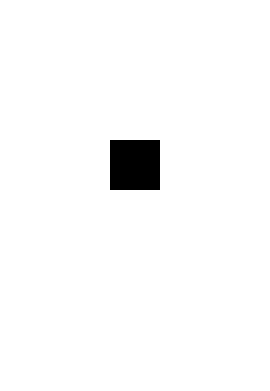

imshow(log(cilia.Results(1).Box(1).Iqtau), 'XData', [1 256])

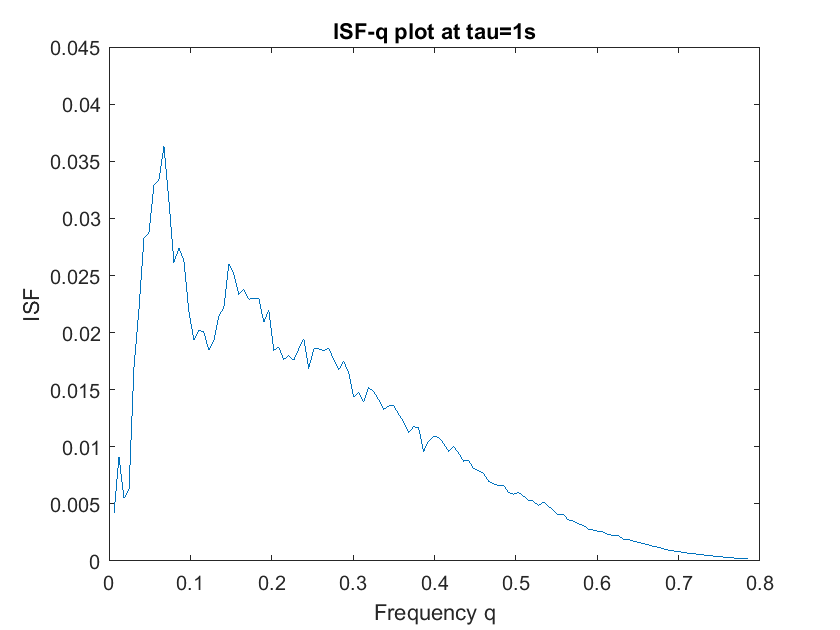

tau=10;
max_Iqtau=max(max(cilia.Results(1).Box(1).Iqtau));
plot(0.5*cilia.Results(1).qVec,cilia.Results(1).Box(1).Iqtau(1:128,tau))
ylim([0 max_Iqtau])
xlabel('Frequency q')
ylabel('ISF')
title(['ISF-q plot at tau=' num2str(tau/10) 's'])

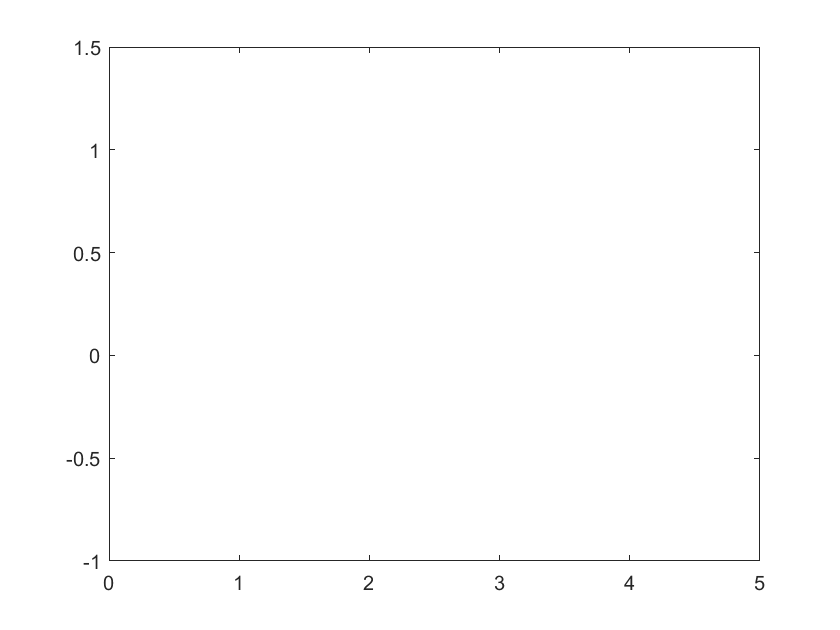

cilia.Results(1).Box(1).Iqtau

ans =     0.0001    0.0003    0.0005    0.0007    0.0010    0.0012    0.0013    0.0017    0.0019    0.0022    0.0023    0.0026    0.0030    0.0031    0.0032    0.0036    0.0041    0.0042    0.0043    0.0045    0.0045    0.0052    0.0048    0.0049    0.0049    0.0051    0.0049    0.0050    0.0052    0.0049    0.0041    0.0040    0.0036    0.0035    0.0041    0.0032    0.0029    0.0023    0.0039    0.0011    0.0020    0.0026    0.0007    0.0031    0.0003    0.0002    0.0016    0.0001    0.0000    0.0000
    0.0001    0.0002    0.0004    0.0005    0.0007    0.0009    0.0010    0.0012    0.0013    0.0016    0.0018    0.0020    0.0021    0.0024    0.0024    0.0025    0.0028    0.0027    0.0030    0.0031    0.0030    0.0036    0.0038    0.0033    0.0028    0.0033    0.0031    0.0038    0.0032    0.0034    0.0032    0.0024    0.0031    0.0027    0.0026    0.0020    0.0022    0.0016    0.0027    0.0010    0.0014    0.0014    0.0006    0.0020    0.0003    0.0002    0.0010    0.0000    0.0000   

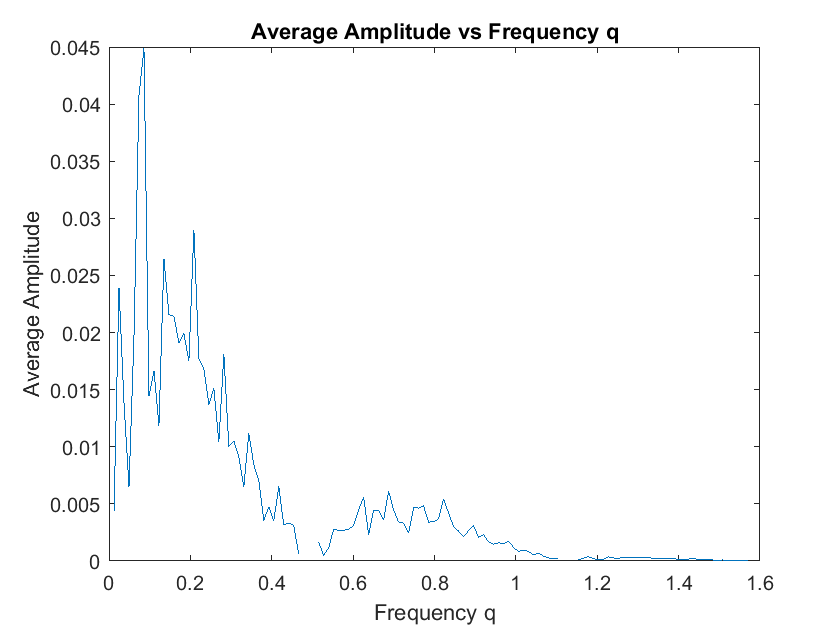

clc
clear

name = 'fx_0.2_fy_0.2_fxy_0_tauc_0_xc_0_yc_0_freq_0.3.mat';
load(name);
    
    path = [name '_heatmap_plots/'];
    
    if ~exist(path, 'dir')
       mkdir(path)
    end
    
    filename = 'Average Amplitude vs Frequency q.png';
    plot(cilia.Results(1).qVec,cilia.Results(1).AverageAmplitude_vs_q)
    xlabel('Frequency q')
    ylabel('Average Amplitude')
    title('Average Amplitude vs Frequency q')
    saveas(gcf,[path filename])

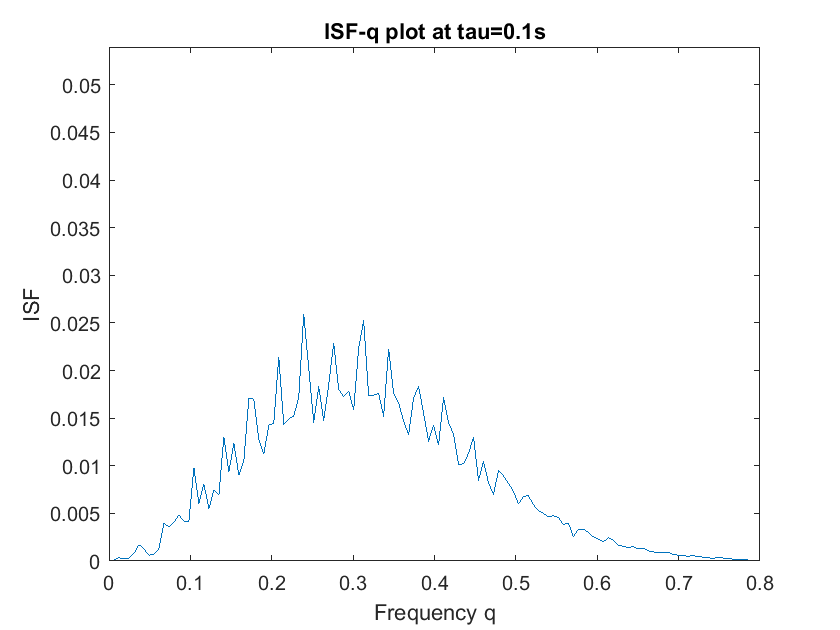

    clf
    
    max_Iqtau=max(max(cilia.Results(1).Box(1).Iqtau));
    for tau =1:size(cilia.Results(1).Box(1).Iqtau,2)
        filename = ['ISF-q plot at tau=' num2str(tau/10) 's.png'];
        plot(0.5*cilia.Results(1).qVec,cilia.Results(1).Box(1).Iqtau(1:128,tau))
        ylim([0 max_Iqtau])
        xlabel('Frequency q')
        ylabel('ISF')
        title(['ISF-q plot at tau=' num2str(tau/10) 's'])
        saveas(gcf,[path filename])
        clf
    end